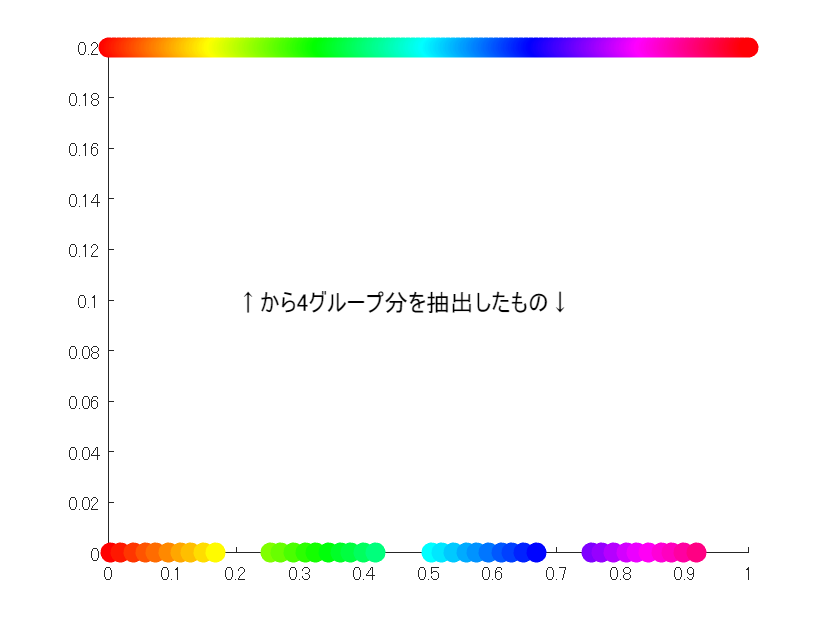

clear;

color_list = [10 10 10 10];
color_group = length(color_list);
[cptn,cptn_idx]= setColorPtn(color_list,[],[],1/3);
% colororder(cptn); % 色指定ありなしでの差異を見るので、後で実施。

% 描画用カラーパターン生成のテスト
scatter(cptn_idx/256,linspace(0,0,length(cptn)),100, cptn, 'filled');
hold on;
scatter(linspace(0,1,256),linspace(0.2,0.2,256),100, hsv(256), 'filled');
text(0.2,0.1,sprintf('↑から%dグループ分を抽出したもの↓',color_group),'FontSize',12)
hold off;

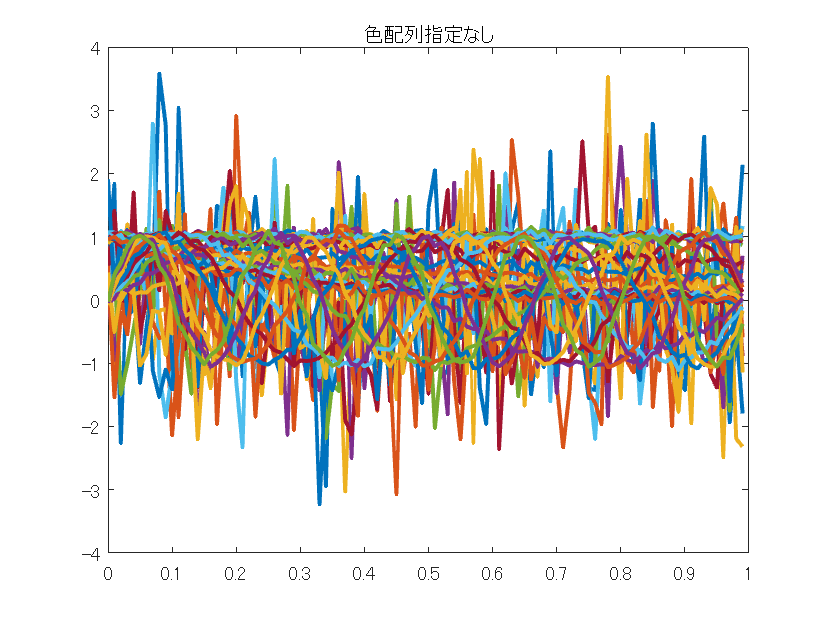

Fs = 100;            % サンプリング周波数
T = 1/Fs;             % サンプリング時間
L = 100;             % 信号の長さ
t = (0:L-1)*T;        % 時間ベクトル

data = zeros(40, L);

rng("default")

% 1. 乱数
for i = 1:10
    data(i, :) = randn(1, L);
end

% 2. 一定値
for i = 11:20
    data(i, :) = 1 + 0.05*randn(1, L);
end

% 3. 0へ減少する指数関数
decay_constants = linspace(0.5, 5, 10);  % 10種類の減衰定数
for i = 21:30
    data(i, :) = exp(-decay_constants(i-20)*t) + 0.05*randn(1, L);
end

% 4. 正弦波
frequencies = linspace(0.5, 5, 10);  % 10種類の周波数
for i = 31:40
    data(i, :) = sin(2*pi*frequencies(i-30)*t) + 0.05*randn(1, L);
end

figure;
for i = 1:40
    plot(t,data(i,:),'LineWidth',2)
    hold on;
end
title('色配列指定なし')
hold off;

カラーパターン指定で再度描画

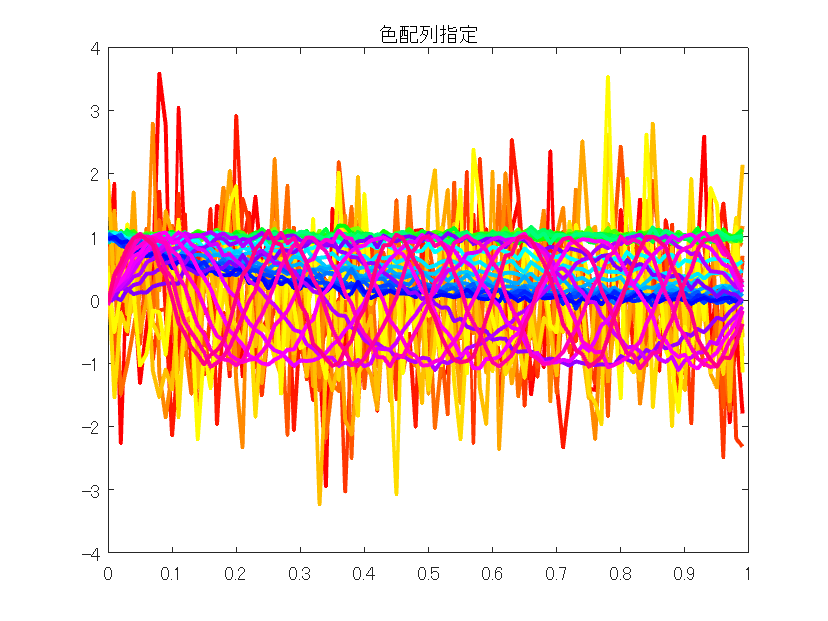

figure;
colororder(cptn);

for i = 1:40
    plot(t,data(i,:),'LineWidth',2)
    hold on;
end
title('色配列指定')
hold off;